# Models of Stochastic Processes

## 1. Wiener Process

### 1.1 Non correlated Brownian Motion

A Weiner process, also called Brownian motion, is a model for stochastic processes (for more info: [Wikipedia](https://en.wikipedia.org/wiki/Wiener_process)). For every Wiener process $W_t$, we can write:


$${\left\lbrace \begin{array}{cc}
{W_{t+1} \;=\;W}_t +N\left(0,\Delta t\right) & \\
W_0 =0 & 
\end{array}\right.}$$
 

Looking at some simulations of a Weiner process in 4 dimensions, we have:

Nb_trj = 10000;
N = 366;
Te = 1/(N-1);
t = 0:Te:1;
dim = 4;
M = zeros(dim,Nb_trj, N);
randM = normrnd(0,sqrt(Te),dim,Nb_trj,N);
for time=2:1:N
   M(:,:,time) = M(:,:,time-1) + randM(:,:,time); 
end

Plotting the movement in one of four dimensions:

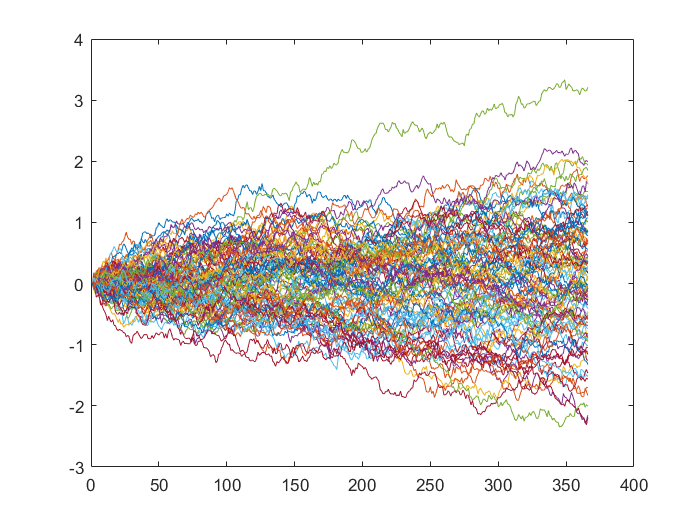

figure
for i = 1:100
   temp = M(1,i,:);
   plot(temp(:))
   hold on
end

Next, we confirm the mean and varaiance of the process.

points = [10 100 300];
m=zeros(dim, 3);
sigma=zeros(dim, 3);
for d = 1:1:4
    for i=1:1:3
        m(d,i) = mean(M(d,:,points(i)));
        sigma(d,i) = std(M(d,:,points(i)));
    end    
end
m, sigma

m =    -0.0059   -0.0104   -0.0047
   -0.0025   -0.0103   -0.0040
    0.0003   -0.0006   -0.0060
    0.0016    0.0022   -0.0116


sigma =     0.1581    0.5171    0.8974
    0.1588    0.5196    0.9119
    0.1578    0.5140    0.9060
    0.1549    0.5170    0.9063


We see that the mean value at the chosen onstants is close to 0, and can be predicted fromt he theory. The standard deviation for each instant $k\Delta t$ should be $\sqrt{k\Delta t}$, since each instance of $W_t$ is independant. TO further confirm independance between the dimensions, we can calculate the cross-correlation between different dimensions.

corMatrix_10_12 = corrcoef(M(1,:,10),M(2,:,10));
corMatrix_10_13 = corrcoef(M(1,:,10),M(3,:,10));
corMatrix_10_14 = corrcoef(M(1,:,10),M(4,:,10));
corMatrix_10_23 = corrcoef(M(2,:,10),M(3,:,10));
corMatrix_10_24 = corrcoef(M(2,:,10),M(3,:,10));
corMatrix_10_34 = corrcoef(M(3,:,10),M(4,:,10));

corMatrix_100_12 = corrcoef(M(1,:,100),M(2,:,100));
corMatrix_100_13 = corrcoef(M(1,:,100),M(3,:,100));
corMatrix_100_14 = corrcoef(M(1,:,100),M(4,:,100));
corMatrix_100_23 = corrcoef(M(2,:,100),M(3,:,100));
corMatrix_100_24 = corrcoef(M(2,:,100),M(3,:,100));
corMatrix_100_34 = corrcoef(M(3,:,100),M(4,:,100));

corMatrix_300_12 = corrcoef(M(1,:,300),M(2,:,300));
corMatrix_300_13 = corrcoef(M(1,:,300),M(3,:,300));
corMatrix_300_14 = corrcoef(M(1,:,300),M(4,:,300));
corMatrix_300_23 = corrcoef(M(2,:,300),M(3,:,300));
corMatrix_300_24 = corrcoef(M(2,:,300),M(3,:,300));
corMatrix_300_34 = corrcoef(M(3,:,300),M(4,:,300));

corMatrix_12 = (corMatrix_10_12 + corMatrix_100_12 + corMatrix_300_12)/3;
corMatrix_13 = (corMatrix_10_13 + corMatrix_100_13 + corMatrix_300_13)/3;
corMatrix_14 = (corMatrix_10_14 + corMatrix_100_14 + corMatrix_300_14)/3;
corMatrix_23 = (corMatrix_10_23 + corMatrix_100_23 + corMatrix_300_23)/3;
corMatrix_24 = (corMatrix_10_24 + corMatrix_100_24 + corMatrix_300_24)/3;
corMatrix_34 = (corMatrix_10_34 + corMatrix_100_34 + corMatrix_300_34)/3;

corMatrix_12, corMatrix_13, corMatrix_14, corMatrix_23, corMatrix_24, corMatrix_34

corMatrix_12 =     1.0000   -0.0012
   -0.0012    1.0000


corMatrix_13 =     1.0000   -0.0061
   -0.0061    1.0000


corMatrix_14 =     1.0000   -0.0042
   -0.0042    1.0000


corMatrix_23 =     1.0000    0.0096
    0.0096    1.0000


corMatrix_24 =     1.0000    0.0096
    0.0096    1.0000


corMatrix_34 =     1.0000    0.0014
    0.0014    1.0000


### 1.2 Correlated Brownian Motion

Let us assume that we want a specific correlation between each of the dimensions of the brownian motion. For the demonstration, let's fix that as:


$$\Sigma =\left\lbrack \begin{array}{cccc}
1 & 0\ldotp 2 & 0\ldotp 8 & 0\ldotp 5\\
0\ldotp 2 & 1 & 0\ldotp 3 & 0\ldotp 2\\
0\ldotp 8 & 0\ldotp 3 & 1 & 0\ldotp 9\\
0\ldotp 5 & 0\ldotp 2 & 0\ldotp 9 & 1
\end{array}\right\rbrack$$


By Choleski decomposition, we can find a triangular matrix $U\;s\ldotp t\ldotp \Sigma =U^T U$. To have a Weiner process $W_t^{\mathrm{new}}$ whose componants are correlated, we have: $W_t^{\mathrm{new}} ={\mathrm{UW}}_t$.

CorM = [1 0.2 0.8 0.5; 0.2 1 0.3 0.2; 0.8 0.3 1 0.9; 0.5 0.2 0.9 1];
U = chol(CorM);

M_dash = zeros(dim,Nb_trj, N);
for time=2:1:N
   M_dash(:,:,time) = U'*M(:,:,time); 
end

m_dash=zeros(dim, 3);
sigma_dash=zeros(dim, 3);
for d = 1:1:4
    for i=1:1:3
        m_dash(d,i) = mean(M_dash(d,:,points(i)));
        sigma_dash(d,i) = std(M_dash(d,:,points(i)));
    end    
end
m_dash, sigma_dash

m_dash =    -0.0059   -0.0104   -0.0047
   -0.0036   -0.0122   -0.0049
   -0.0049   -0.0101   -0.0078
   -0.0026   -0.0062   -0.0102


sigma_dash =     0.1581    0.5171    0.8974
    0.1586    0.5202    0.9102
    0.1576    0.5163    0.8969
    0.1575    0.5153    0.8989


corMatrix_300_12_dash = corrcoef(M_dash(1,:,300),M_dash(2,:,300))

corMatrix_300_12_dash =     1.0000    0.1910
    0.1910    1.0000


corMatrix_300_13_dash = corrcoef(M_dash(1,:,300),M_dash(3,:,300))

corMatrix_300_13_dash =     1.0000    0.7935
    0.7935    1.0000


corMatrix_300_14_dash = corrcoef(M_dash(1,:,300),M_dash(4,:,300))

corMatrix_300_14_dash =     1.0000    0.4869
    0.4869    1.0000


corMatrix_300_23_dash = corrcoef(M_dash(2,:,300),M_dash(3,:,300))

corMatrix_300_23_dash =     1.0000    0.3035
    0.3035    1.0000


corMatrix_300_24_dash = corrcoef(M_dash(2,:,300),M_dash(3,:,300))

corMatrix_300_24_dash =     1.0000    0.3035
    0.3035    1.0000


corMatrix_300_34_dash = corrcoef(M_dash(3,:,300),M_dash(4,:,300))

corMatrix_300_34_dash =     1.0000    0.8977
    0.8977    1.0000


## 2. Poisson Process

A Poisson process is one where the time interval betweent he arrival of two clients is distributed exponentially


$$\mathrm{Pr}\left(\tau \ge t\right)=\mathrm{exp}\left(-\lambda t\right)\;\;\;\;t\ge 0$$


We can emulate the time instants of $\tau$ which follows the exponential distribution by using the inverse transform sampling. Given a uniform random variable $u\in \left\lbrack 0,1\right\rbrack$, we have $\tau =-\frac{1}{\lambda }\mathrm{ln}\left(1-u\right)$.

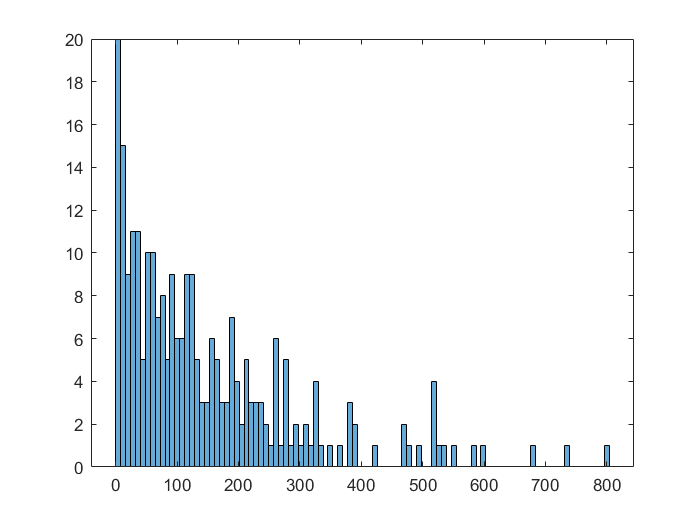

lambda = 1/140;%consider ecart type
n = round(3600*10*lambda - 1);
tau_exp = gen_exp(n,lambda);
BIN = 100;

figure
histogram(tau_exp, BIN)

### Estimating the number of insatisfied clients

To calculate the number of insatisfied clients, we assume that we have on average one request every $\frac{1}{\lambda }$ seconds. We can further model the time for treating a single request using a gaussian distribution, with mean of 120 seconds and a standard deviation of 20 seconds. The aim of this section is to calculate the fraction of people for which the waiting time is greater than 10 minutes in a period of 10 hours. For getting better results, we will use Monte Carlo sampling.

t_traitement = normrnd(120,20,1,n);
iterations = 1000;
irritated_clients_sum = 0;
for it = 1:1:iterations
  [t_attente, t_fin] = attente(tau_exp, t_traitement);
  irritated_clients_sum  = irritated_clients_sum + numel(t_attente(t_attente > 10*60));
end
irritated_clients = irritated_clients_sum/iterations

irritated_clients = 8

## 3. Markov Chains

Given $\left\lbrace Z_n \right\rbrace$ an IID random variable with values in $\left\lbrace +1,-1\right\rbrace$ with the probability distribution

 
$$\mathrm{Pr}\left\lbrace Z_n =1\right\rbrace =p$$


Given another random variable $X_0$ in $\left(Z\right)$ and independant of $\left\lbrace Z_n \right\rbrace$. We define the process $\left\lbrace X_{n+1} \right\rbrace =X_n +Z_n$. We observe that the value of $X_{n+1}$ is only dependant on the current value $X_n$ and not the preceeding values. This is the property of a Markov Chain. We can aslo show this this Markov chain is homogenous:


$$\mathrm{Pr}\left\lbrace x_{n+1} =i+z\;|\;X_n =i\right\rbrace =\mathrm{Pr}\left\lbrace Z=z\right\rbrace$$


Since the distribution of $Z_n$ does not depend on $n$, the Markov chain is homogenous.

We can simulate the Movement of a Markov chain using the code below. We observe that if $p\not= 0\ldotp 5$, there is either a tendenacy to increase (for $p>0\ldotp 5$) or decrease (for $p<0\ldotp 5$) if $n$ is sufficiently large.

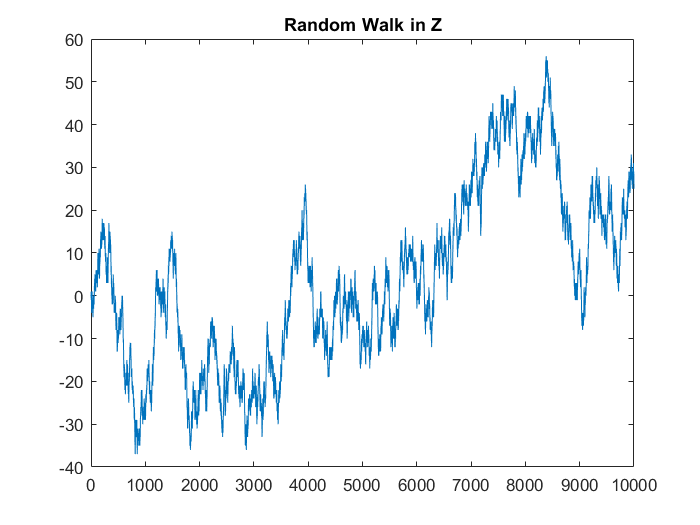

n = 10000;
x = zeros(1,n);
p = 0.5;
for i = 2:n
    if rand()<p
        x(i) = x(i-1) + 1;
    else
        x(i) = x(i-1) - 1;
    end
end

figure
plot(x)
title('Random Walk in Z')

## 4. Diffusion

Given a standard monodimensional brownian motion strating from the origin, the process is a solution for the equation:


$${\mathrm{dX}}_t =a\left(b-X_t \right)\mathrm{dt}+\sigma {\mathrm{dW}}_t$$



$$\Rightarrow X_{t_n } =\frac{1}{1+a\delta t}X_{t_{n-1} } +\mathrm{ab}\delta t+\sigma \delta W_t$$


where $\delta W_t ~N\left(0,\delta t\right)$. Below, we show some trajectories using different values of $a,b$ and $\sigma$.

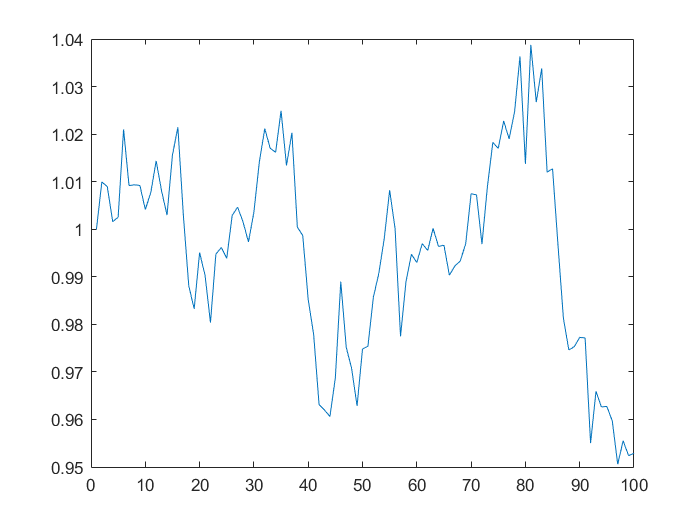

N = 100;
a = 1;
b = 1;
sig = 1;
dt = 0.01;

x = ones(1, N);
for time=2:1:N
   x(time) = (x(time-1) + a*b*dt + sig*normrnd(0,dt))/(1+a*dt);
end
figure
plot(x)

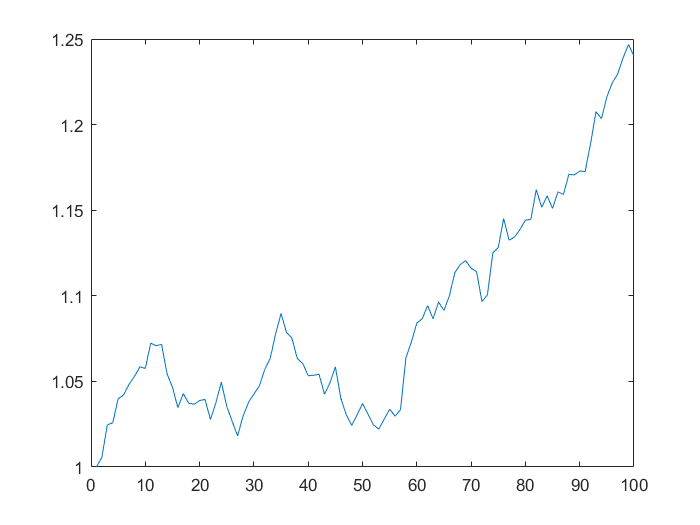

a = -1;
b = 1;
sig = 1;
dt = 0.01;

x = ones(1, N);
for time=2:1:N
   x(time) = (x(time-1) + a*b*dt + sig*normrnd(0,dt))/(1+a*dt);
end
figure
plot(x)

Depending on the run, the above graph can either be inscreaing or decreasing.

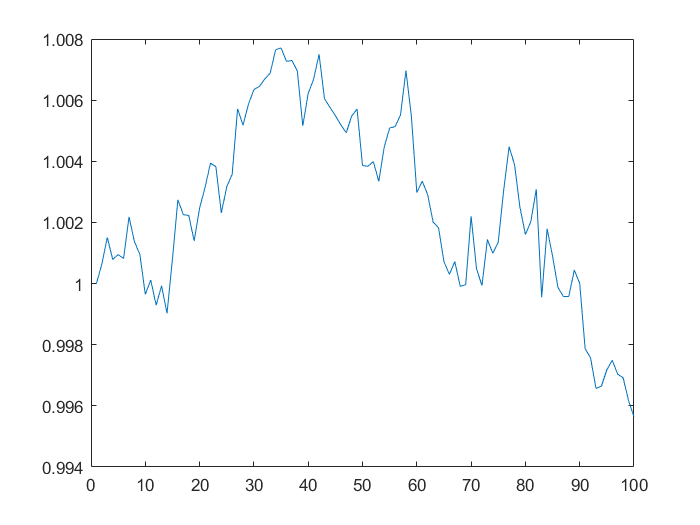

a = -1;
b = 1;
sig = 0.1;
dt = 0.01;

x = ones(1, N);
for time=2:1:N
   x(time) = (x(time-1) + a*b*dt + sig*normrnd(0,dt))/(1+a*dt);
end
figure
plot(x)